# Guía 1 - Ejercicio 2

## Enunciado:

Implemente una red de Hopfield ‘82 que aprenda imágenes binarias a elección. Pruebe el funcionamiento de la red utilizando distintos patrones de entrada como, por ejemplo, las mismas imágenes con ruido o con elementos borrados o agregados. Verifique la existencia de estados espurios en la red. En particular, verifique si los patrones inversos y la mezcla de los tres patrones son estados espurios (Ver Spurious States, en la sección 2.2, Hertz, Krogh & Palmer, pág. 24). 

Importo los datos:

img1 = imread('v.bmp');         % 50x50
img2 = imread('panda.bmp');     % 50x50
img3 = imread('perro.bmp');     % 50x50
img4 = imread('quijote.bmp');   % 45x60
img5 = imread('torero.bmp');    % 45x60
img6 = imread('paloma.bmp');    % 45x60

Las imágenes tienen distintos tamaños, para trabajarlas a todas juntas primero hago un padding para que tengan todas tamaño 50x60. Como quiero que el padding tenga aprox la misma cantidad de unos y ceros, paso la matriz a double y hago un padding de 0,5 así cuando pase la función signo se van a transformar en 1s y 0s.

imgPad1 = padarray(double(img1),[0 5], 0.5, 'both');
imgPad2 = padarray(double(img2),[0 5], 0.5, 'both');
imgPad3 = padarray(double(img3),[0 5], 0.5, 'both');
imgPad4 = padarray(double(img4),[5 0], 0.5, 'pre');
imgPad5 = padarray(double(img5),[5 0], 0.5, 'pre');
imgPad6 = padarray(double(img6),[5 0], 0.5, 'pre');

Imprimo los tamaños para verificar que tengo los mismos tamaños.

size(imgPad1)

ans =     50    60


size(imgPad2)

ans =     50    60


size(imgPad3)

ans =     50    60


size(imgPad4)

ans =     50    60


size(imgPad5)

ans =     50    60


size(imgPad6)

ans =     50    60


Paso las imágenes a -1s y 1s (los valores del padding van a ir a cero).

imgPad1=imgPad1*2-1;
imgPad2=imgPad2*2-1;
imgPad3=imgPad3*2-1;
imgPad4=imgPad4*2-1;
imgPad5=imgPad5*2-1;
imgPad6=imgPad6*2-1;

Paso las imágenes por la función signo y las muestro.

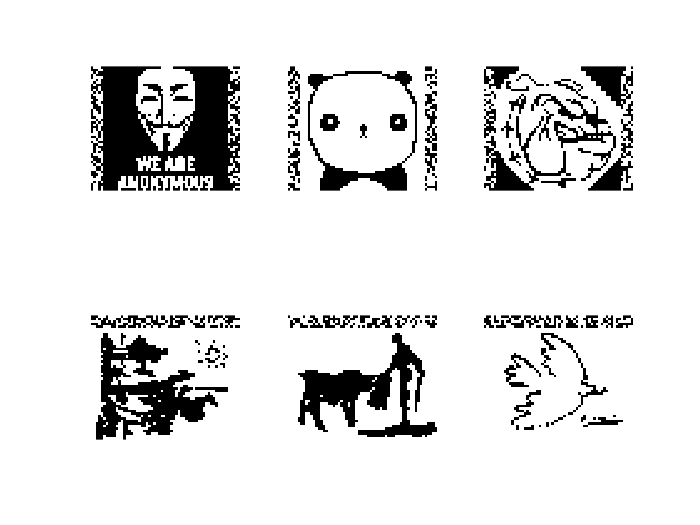

imgPad1 = negSign(imgPad1);
imgPad2 = negSign(imgPad2);
imgPad3 = negSign(imgPad3);
imgPad4 = negSign(imgPad4);
imgPad5 = negSign(imgPad5);
imgPad6 = negSign(imgPad6);
figure();
hold on;
subplot(2,3,1);
imshow(imgPad1,'InitialMagnification','fit');
subplot(2,3,2);
imshow(imgPad2,'InitialMagnification','fit');
subplot(2,3,3);
imshow(imgPad3,'InitialMagnification','fit');
subplot(2,3,4);
imshow(imgPad4,'InitialMagnification','fit');
subplot(2,3,5);
imshow(imgPad5,'InitialMagnification','fit');
subplot(2,3,6);
imshow(imgPad6,'InitialMagnification','fit');

Las imágenes estan en formato de matrices, paso a vectores.

imgVector1=imgPad1(:);
imgVector2=imgPad2(:);
imgVector3=imgPad3(:);
imgVector4=imgPad4(:);
imgVector5=imgPad5(:);
imgVector6=imgPad6(:);

Por motivos de comodidad paso meto todos los patrones en una sola matriz de patrones, donde cada columna va a ser un patrón.

matrizPatrones = zeros([length(imgVector1) 6]);
matrizPatrones(:,1) = imgVector1;
matrizPatrones(:,2) = imgVector2;
matrizPatrones(:,3) = imgVector3;
matrizPatrones(:,4) = imgVector4;
matrizPatrones(:,5) = imgVector5;
matrizPatrones(:,6) = imgVector6;

Creo la matriz de pesos sinápticos. 

matrizPesosSinapticos = matrizPatrones*matrizPatrones';

## Caso sincrónico

Elijo una imagen al azar, la muestro, la paso por la red y verifico que haya sido aprendida.

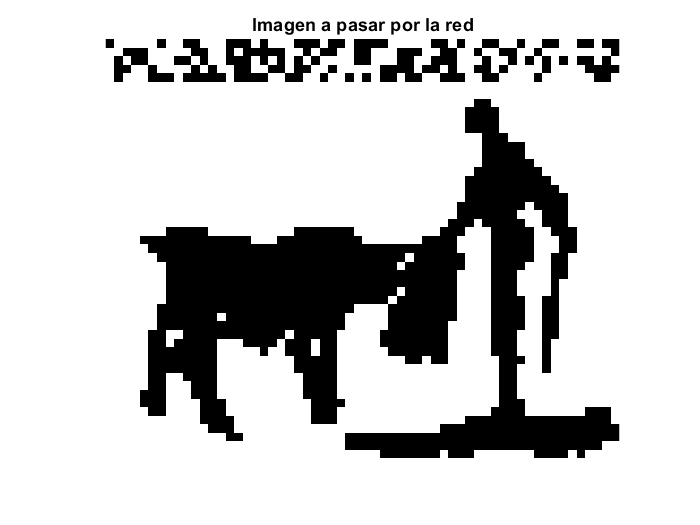

patron = randi(6,1);
figure()
imshow(reshape(matrizPatrones(:,patron),[50 60]),'InitialMagnification','fit');
title('Imagen a pasar por la red');

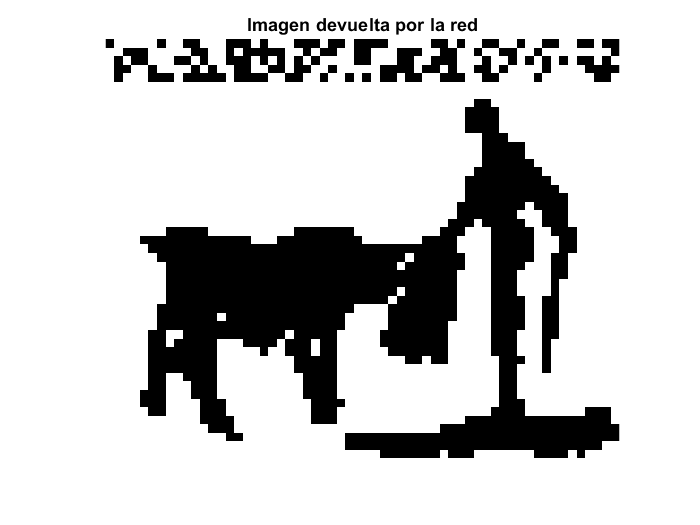

salida = matrizPesosSinapticos*matrizPatrones(:,patron);
salida = negSign(salida);
imshow(reshape(salida,[50 60]),'InitialMagnification','fit');
title('Imagen devuelta por la red');

Verifico que sean la misma imagen.

if isequal(salida,matrizPatrones(:,patron))
    disp('IGUALES');
else 
    disp('DISTINTAS');
end

IGUALES


## Ruido salt & pepper

Agrego ruido tipo salt and pepper a la misma imagen. La variable ruidoSyP va de 0 a 100 e indica el porcentaje de ruido.

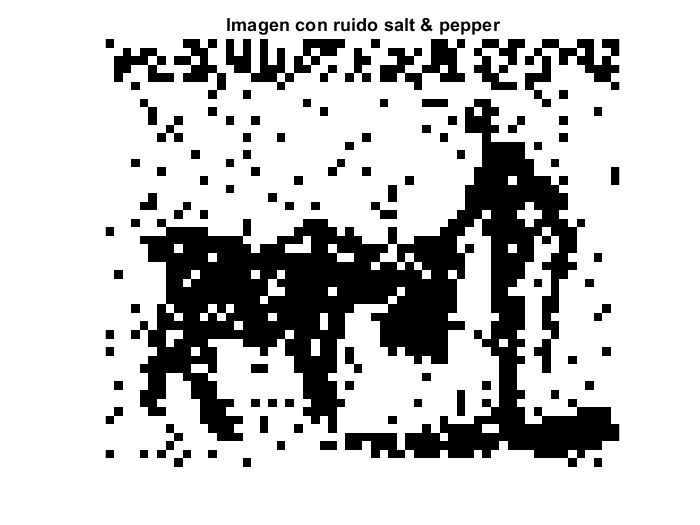

ruidoSyP = 20.0;
vectorRuido = rand(size(matrizPatrones(:,patron))) < ruidoSyP/100.0;
patronRuidoso = negSign(matrizPatrones(:,patron).*(1-vectorRuido));
imshow(reshape(patronRuidoso,[50 60]),'InitialMagnification','fit');
title('Imagen con ruido salt & pepper');

salida = matrizPesosSinapticos*patronRuidoso;
salida = negSign(salida);
imshow(reshape(salida,[50 60]),'InitialMagnification','fit');
title('Imagen devuelta por la red');

Verifico que sea igual a la imágen original

if isequal(salida,matrizPatrones(:,patron))
    disp('IGUALES');
else 
    disp('DISTINTAS');
end

IGUALES


## Ruido de tipo flip

Doy vuelta un porcentaje de los valores de la imagen indicado por ruidoFlip. Si ruidoFlip=100 equivale al negativo de la imagen

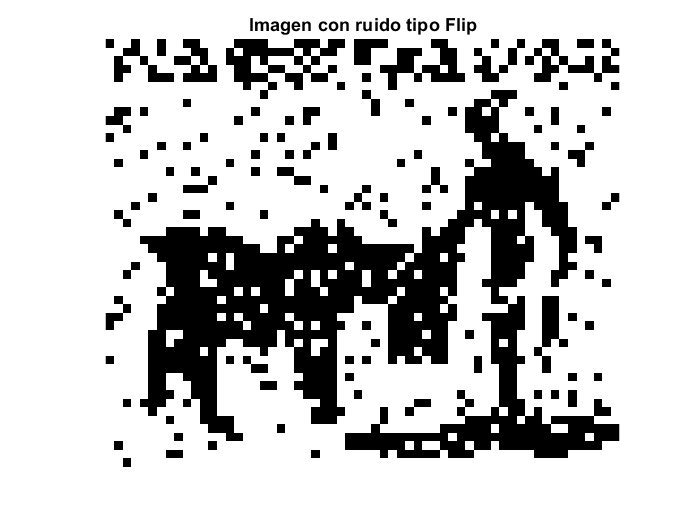

ruidoSyP = 10.0;
vectorRuido = rand(size(matrizPatrones(:,patron))) < ruidoSyP/100.0;
patronRuidoso = matrizPatrones(:,patron).*(1-2*vectorRuido);
imshow(reshape(patronRuidoso,[50 60]),'InitialMagnification','fit');
title('Imagen con ruido tipo Flip');

salida = matrizPesosSinapticos*patronRuidoso;
salida = negSign(salida);
imshow(reshape(salida,[50 60]),'InitialMagnification','fit');
title('Imagen devuelta por la red');

if isequal(salida,matrizPatrones(:,patron))
    disp('IGUALES');
else 
    disp('DISTINTAS');
end

IGUALES


## Caso asincrónico

Elijo una imagen al azar, la muestro, la paso por la red y verifico que haya sido aprendida.

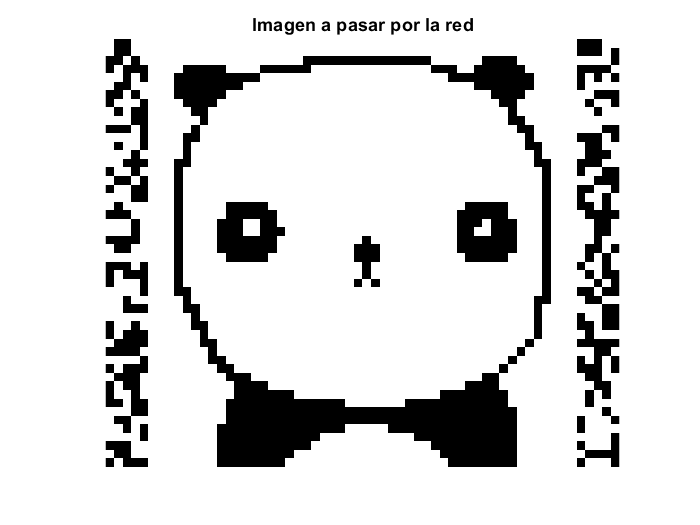

patron = randi(6,1);
figure()
imshow(reshape(matrizPatrones(:,patron),[50 60]),'InitialMagnification','fit');
title('Imagen a pasar por la red');

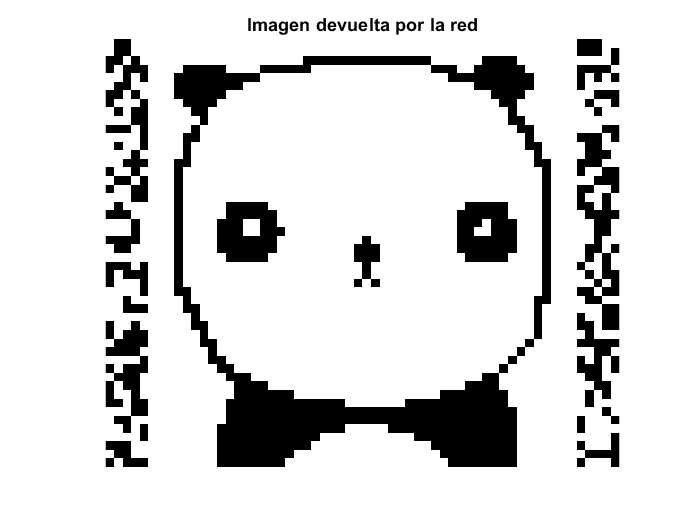

salida = actualizacionAsincronica(matrizPesosSinapticos,matrizPatrones(:,patron));
imshow(reshape(salida,[50 60]),'InitialMagnification','fit');
title('Imagen devuelta por la red');

Verifico que sea igual a la imágen original

if isequal(salida,matrizPatrones(:,patron))
    disp('IGUALES');
else 
    disp('DISTINTAS');
end

IGUALES


## Ruido salt & pepper

Agrego ruido tipo salt and pepper a la misma imagen. La variable ruidoSyP va de 0 a 100 e indica el porcentaje de ruido.

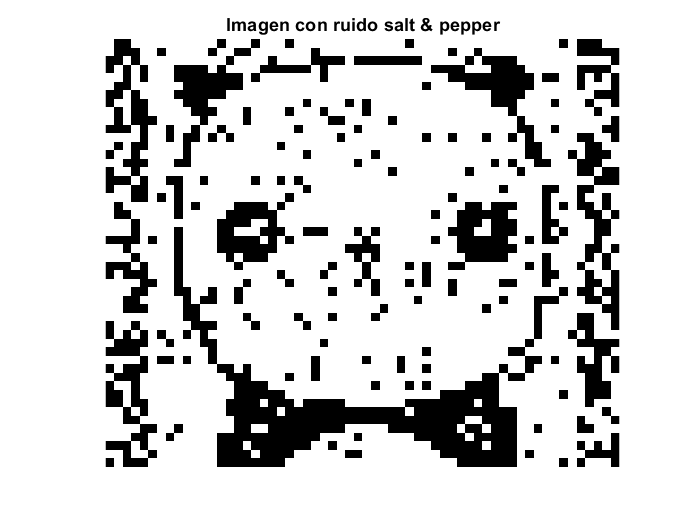

ruidoSyP = 20.0;
vectorRuido = rand(size(matrizPatrones(:,patron))) < ruidoSyP/100.0;
patronRuidoso = negSign(matrizPatrones(:,patron).*(1-vectorRuido));
imshow(reshape(patronRuidoso,[50 60]),'InitialMagnification','fit');
title('Imagen con ruido salt & pepper');

salida = actualizacionAsincronica(matrizPesosSinapticos,matrizPatrones(:,patron));
imshow(reshape(salida,[50 60]),'InitialMagnification','fit');
title('Imagen devuelta por la red');

Verifico que sea igual a la imágen original

if isequal(salida,matrizPatrones(:,patron))
    disp('IGUALES');
else 
    disp('DISTINTAS');
end

IGUALES


## Ruido de tipo flip

Doy vuelta un porcentaje de los valores de la imagen indicado por ruidoFlip. Si ruidoFlip=100 equivale al negativo de la imagen

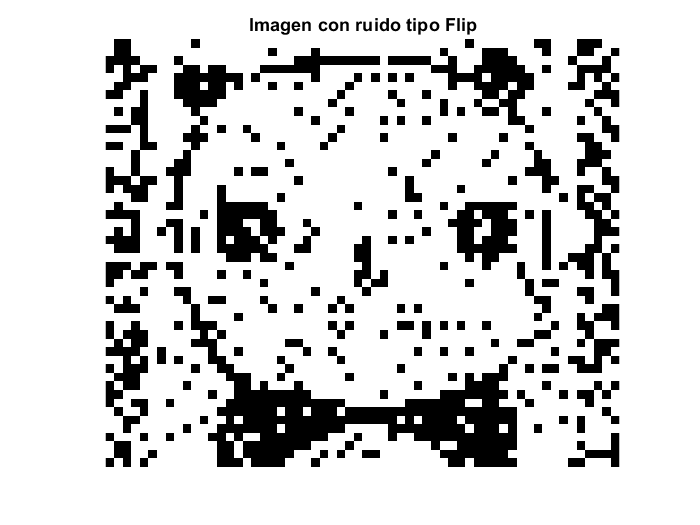

ruidoSyP = 10.0;
vectorRuido = rand(size(matrizPatrones(:,patron))) < ruidoSyP/100.0;
patronRuidoso = matrizPatrones(:,patron).*(1-2*vectorRuido);
imshow(reshape(patronRuidoso,[50 60]),'InitialMagnification','fit');
title('Imagen con ruido tipo Flip');

salida = actualizacionAsincronica(matrizPesosSinapticos,matrizPatrones(:,patron));
imshow(reshape(salida,[50 60]),'InitialMagnification','fit');
title('Imagen devuelta por la red');

Verifico que sea igual a la imágen original

if isequal(salida,matrizPatrones(:,patron))
    disp('IGUALES');
else 
    disp('DISTINTAS');
end

IGUALES


## Compruebo que las combinaciones lineales impares sean estados espúrios

cantPatrones = randi(2,1);
if cantPatrones==1
    cantPatrones = 3
else
    cantPatrones=5
end

cantPatrones = 5

eleccionPatrones = randperm(cantPatrones)

eleccionPatrones =      5     4     2     3     1


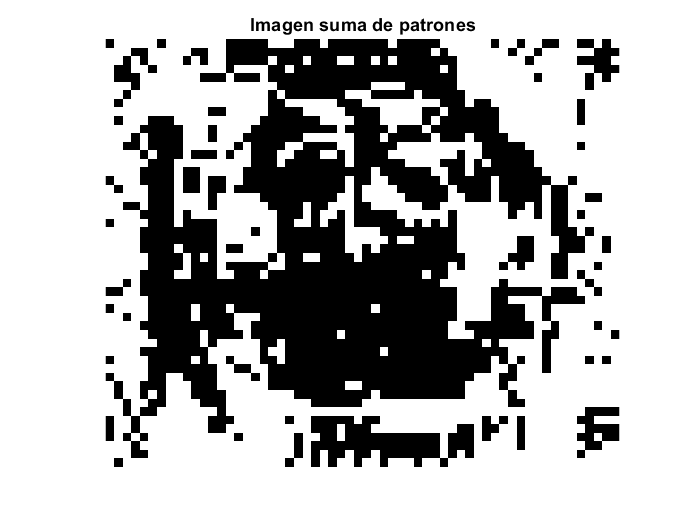

sumaPatrones = zeros(size(matrizPatrones(:,1)));

for i=1:cantPatrones
    sumaPatrones = sumaPatrones+(2*randi(2,1)-3)*matrizPatrones(:,eleccionPatrones(i));
end
sumaPatrones = negSign(sumaPatrones);%Puedo usar sign() ya que no va a haber ceros
imshow(reshape(sumaPatrones,[50 60]),'InitialMagnification','fit');
title('Imagen suma de patrones');

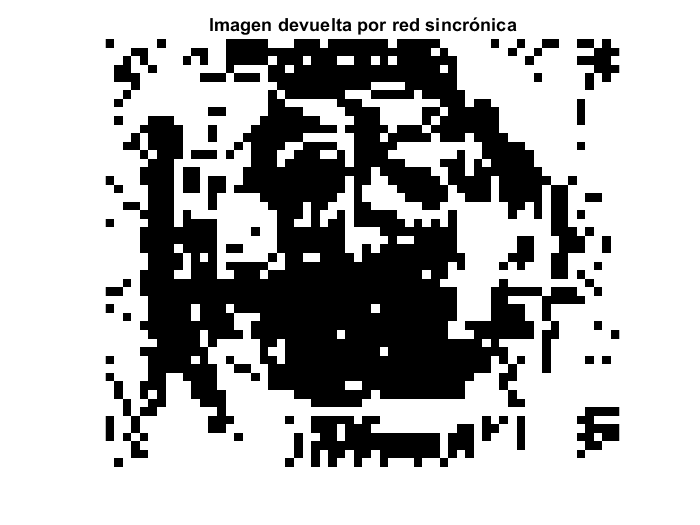



salida = matrizPesosSinapticos*sumaPatrones;
salida = negSign(salida);
imshow(reshape(salida,[50 60]),'InitialMagnification','fit');
title("Imagen devuelta por red sincrónica")

if isequal(sumaPatrones,salida)
    disp('IGUALES');
else 
    disp('DISTINTAS');
end

IGUALES


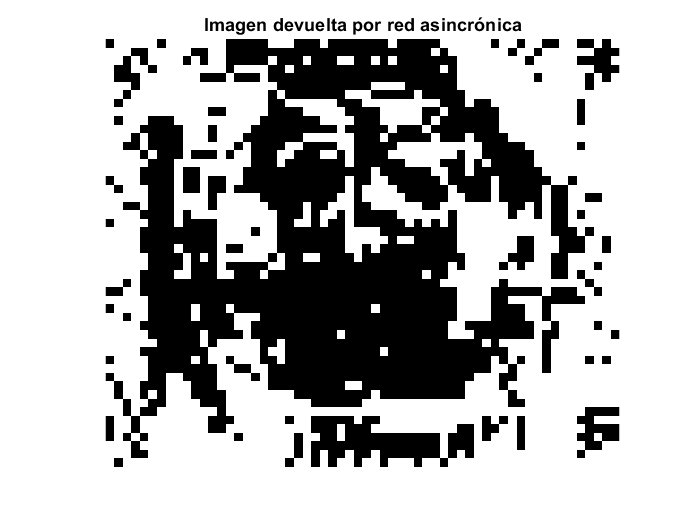


salida = actualizacionAsincronica(matrizPesosSinapticos,sumaPatrones);
imshow(reshape(salida,[50 60]),'InitialMagnification','fit');
title('Imagen devuelta por red asincrónica');


if isequal(sumaPatrones,salida)
    disp('IGUALES');
else 
    disp('DISTINTAS');
end

IGUALES
